# Creación de archivos .m y .mlx de función

El lenguaje de programación MATLAB se construye alrededor de funciones. Una *función* es una pieza de código de computación que acepta un argumento de entrada del usuario (`input`) y produce una salida al programa (`output`).

- No confundir los `input` de las funciones con el comando `input` (que se estudará más adelante), y lo mismo para los `output`.

En esencia, las funciones son las que ayudan a programar eficientemente para evitar reescribir código de tareas que se realizan con frecuencia.

En MATLAB las funciones se las puede crear de dos formas: mediante la palabra reservada `function` o desde la barra de menú, en el menú HOME, luego New y eligiendo si se quiere crear una **function** o una **live function**.

Una diferencia entre ambas funciones es la extensión: la primera es .m (como un script) y la segunda es .mlx (como un live script). Entonces en la carpeta donde se las guarde no se diferenciarán los archivos funciones de los archivos scripts, sin embargo, en el *current folder* si se diferenciará cuál archivo es una función y cuál no.

Otra diferencia es el entorno de trabajo porque una **function** .m trabajará con el entorno del *editor* mientras que una live function trabajará con el entorno del *live editor* (en el que nos encontramos actualmente).

Sin embargo, indistintamente del entorno y extensión, las funciones tienen la misma estructura y propósito.

**Recomendación:** En ese capítulo de funciones se recomienda sobremanera revisar los ejercicios, ejemplos o problemas debido a que las funciones no son lo mismo que los script. Por ende, en los live script de teoría/apuntes de este capítulo rara vez se incluirá código. Únicamente se trabajará con código de ejemplo.

**Recomendación:** A pesar que no hay diferencia en el modo de trabajar con una función .m y una .mlx, se recomienda trabajar con funciones .m debido a que se las puede ir depurando en la ventana de comandos, mientras que las .mlx no. Es decir, se puede ir probando el código de una función .m a medida que se la va creando con tan sólo ejecutarla, mientras que el código de una función .mlx no es posible probar a menos que escriba dicho código en la ventana de comandos.

## Sintaxis

Tanto las funciones internas que ha definido MATLAB como las que podemos definir nosotros siguen la misma estructura:

- Tiene un **nombre**.

- Tiene **argumento**.

- Tiene **salida**.

Aunque existen funciones que pueden tener más argumentos, salidas o simplemente no tener ni argumento ni salida, ahora nos centraremos en estudiar las funciones más comunes: con un argumento y una salida.

Por ejemplo, la función `cos(x)`:

- Su nombre es **cos**.

- Su argumento es **x**.

- Su salida es el cálculo del coseno de **x**.

Un detalle importante es que el nombre de las funciones debe ser autoexplicativo. Es decir, de una u otra forma debe explicar lo que hace la función en cuestión.

Las funciones se definen para que hagan algo en particular, por ende, no es necesario ver el código fuente. Lo importante es obtener un resultado lógico.

Se refiere un resultado lógico a que, por ejemplo, la función `cos(x)` necesariamente da como salida un número entre -1 y 1 (asumiendo que se le da como argumento un escalar). Si el resultado fuera `-5` o `9`, por ejemplo, sabemos que algo está mal.

Por lo tanto, las funciones que se definan deben devolver un resultado lógico con respecto a lo que se espera que determinen.

Cabe mencinar que todas las convenciones de nomenclatura de MATLAB que se aprendieron para nombrar variables se aplican para nombrar funciones.

### Ejemplo

Asumamos que vamos a necesitar determinar el valor del polinomio $P(x)=3x^3+5x^2-2x+1$ para cualquier valor de $x$. Entonces podemos determinar la siguiente función:

Entonces, el nombre de la fución es **poly**, su argumento es **x** y su salida es **result**.

Una vez definida la función, MATLAB la reconocería como cualquier otra función (como reconoce la función sin, cos, etc.). Bastaría ir dándole valores al argumento para obtener el valor del polinomio.

**Nota:** El nombre de la función debe ser el mismo que el nombre del archivo.

**Nota:** No se añade como código el ejemplo dado porque una función, cuando se define dentro de un script .mlx, siempre va al final. Ya se detallará esto más adelante.

## Comentarios

### Para function .m

Como bien se sabe, es una buena práctica comentar el código de modo que sea sencillo entenderlo. Sin embargo, en una función MATLAB, los comentarios en la línea inmediatamente siguiente a la primera línea tienen un papel especial. Estos comentarios se recuperan con el comando `help` cuando consulte por ayuda de su función (como es función, puede consultarla como cualquier otra de MATLAB).

Retomando el código de ejemplo anterior:

A ejecutar el comando `help` y el nombre de la función

devolvería

**Nota:** Se hace hincapié en que sólo se devolverán los comentarios en la línea inmediatamente siguiente a la primera línea.

**Nota:** Si se añaden más comentarios también aparecerán, pero no como descripción principal de la función si no como descripciones secundarias.

### Para live function .mlx

Para las live function .mlx no se utilizan los comentarios. En lugar de ello lo que se utiliza es un bloque de texto (como el que se está usando actualmente) para las descripciones. Sólo el primer bloque de texto, que va antes del bloque donde se definirá la función, aparecerá como descripción de la función.

Si se quiere dar más detalles de la función y no alargar demasiado la primera línea del bloque de texto, basta dar un intro para que la primera línea sea la descripción principal y el resto de líneas sean descripción secundaria.

**Nota:** Revisar los comentarios de las `live function` creadas para el **ep1**.

## Funciones con entradas y salidas múltiples

Como se mencionó al inicio, existen funciones de múltiples entradas, salidas, ambas o ninguna. La estructura cambia ligeramente, pero la esencia de una función se mantiene.

### Múltiples entradas

Vea el siguiente ejemplo de código:

Como se puede ver, la función `g` recibe dos argumentos y devuelve una salida (que sería la multiplicación de los argumentos).

Algo a destacar del ejemplo es que el cálculo se hizo en una variable `a` pero la salida se igualó a esa variable. Entonces la salida sigue siendo el producto puesto que esa variable calculó esto.

**Nota:** Algunas de las funciones de MATLAB que requieren múltiples entradas son `rem`, `mod`, `meshgrid`, etc.

### Múltiples salidas

Vea el siguiente ejemplo de código:

Como se observa, la función `motion` tiene 1 argumento y 3 salidas.

Sin embargo, si se llama a la función `motion` sin especificar las 3 salidas, sólo se regresará la primera salida.

En cambio, especificando las 3 salidas se obtiene cada valor de la función.

**Nota:** Algunas de las funciones de MATLAB que devuelven múltiples salidas son `max`, `min`, `meshgrid`, etc.

### Múltiples entradas y salidas

Como ya se podrá imaginar, si se unen los conceptos para múltiples entradas y múltiples salidas se puede obtener funciones de múltiples entradas y salidas.

El mejor ejemplo de este tipo de funciones es la función `meshgrid`.

## Funciones sin entrada y sin salida

Aunque la mayoría de las funciones necesitan al menos una entrada y regresan al menos un valor de salida, en algunas situaciones no se requieren ni entradas ni salidas.

Por ejemplo, considere esta función, que dibuja una estrella en coordenadas polares:

Los corchetes de la primera línea indican que la salida de la función es una matriz vacía (es decir: no se regresa valor). Los paréntesis vacíos dicen que no se espera entrada.

Si se ejecuta la función `star` se obtendría el dibujo de una estrella en coordenadas polares.

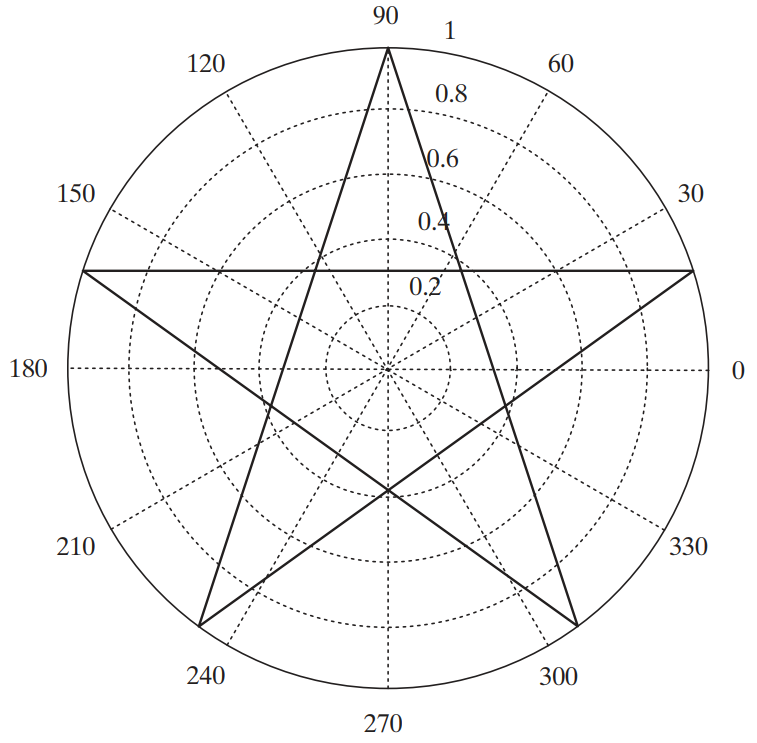

Se podría pensar que en realidad sí hay una salida, justamente la gráficar polar, pero si asigna la función `star` a alguna variable, esta quedaría vacía. O por defecto saldría error.

Por definición, una salida es un valor que se devuelve al ingresar un argumento, pero la función star no devuelve nada. Por eso es una función sin entradas y sin salidas.

**Nota:** Un excelente ejemplo que proporciona MATLAB de una función sin entradas y sin salidas es la función `sphere`. Sin embargo, por supuesto que hay más funciones.

% Su código va aquí :)

## Determinación del número de argumentos de entrada y salida

En alguna ocasión usted querrá conocer el número de argumentos de entrada o valores de salida asociados con una función. MATLAB proporciona dos funciones internas para este propósito.

### Función `nargin`

La función `nargin` indica el número de argumentos que se deben ingresar en una función.

La función consultada debe ser ingresada como cadena.

% Su código va aquí :)

¿Por qué la función `surf` indica -1 argumentos? Bueno, algunas funciones aceptan variables argumentos. Es decir, la función `surf` puede tomar 1 argumento que sería el valor para **z** y los ejes **x** y **y** serían los índices del argumento ingresado, o bien se puede ingresar los 3 argumentos. Esto indica el valor -1 de `nargin`, variables argumentos de entrada.

### Función `nargout`

La fución `nargout` es similar a la función `nargin`, sin embargo, esta indica el número de salidas de una función.

% Su código va aquí :)

## Variables locales

Básicamente son las variables con las que se trabaja dentro de una función, y son locales justamente porque sólo existen y están definidas dentro de la función.

Reciclando el ejemplo de código anterior:

tenemos que las variables **a**, **x**,** y** y **output** son locales. Es decir, sólo están definidas dentro de la función **g**, fuera de la función no están definidas.

Para probar esto, pruebe a crear una función (la función **g** mismo si quiere). Antes de usarla, limpie el área de trabajo con el comando `clear` y llame a la función **g**. Notará que sólo habrá en el área de trabajo `ans` y el valor devuelto de la función. O si asigna la función **g** a alguna variable, sólo estará esa variable.

Así se verifica que las variables dentro de una función son locales.

Además, así como no se puede acceder a las variables locales fuera de la función, dentro de la función tampoco se puede acceder a variables definidas en el área de trabajo.

Se podría decir que una función es un espacio cerrado donde sólo se trabaja con las variables que se definen allí.

## Variables globales

También existen variables globales que, en esencia, son variables con las que se puede trabajar desde dentro una función como fuera de esta.

Sin embargo, NO SE RECOMIENDA SU USO debido a la facilidad para cometer errores cuando no se tiene precaución al establecerlas.

Por ende, sólo se hace mención de su existencia más no se las detallará. Si de cualquier manera se requiere conocerlas, se puede consultar la documentación.

## Acceso a código de archivo .m

Las funciones proporcionadas con MATLAB son de dos tipos. Un tipo es interno y el código no es accesible para que el usuario lo revise. El otro tipo consiste en archivos .m, que se almacenan en cajas de herramientas proporcionadas con el programa. Estos archivos .m (o los archivos .m que uno escribe) se pueden ver con el comando `type`. 

**Nota**: No se hace distinción entre un archivo .m o .mlx porque lo que se está consultando es el código fuente de una función, independientemente de su extensión.

Por ejemplo, se podría consultar el código de la función `sphere`.

% Su código va aquí :)